# Campo de fuerza central de hooke

clc ; clear ; close all ; format short

Hooke's law in circular coordinates


$$F\left(r\right)=-k\left(r-r_0 \right)\hat{r}$$



$$r=\sqrt{x^2 +y^2 }$$



$$x=\textrm{rcos}\theta \to \cos \theta =\frac{x}{\sqrt{x^2 +y^2 }}$$



$$y=\textrm{rsin}\theta \to \sin \theta =\frac{y}{\sqrt{x^2 +y^2 }}$$



$$\hat{r} =\cos \theta \hat{i} +\sin \theta \hat{j}$$


Hooke's law in cartesian coordinates


$$F\left(x,y\right)=-\mathrm{kx}\left(1-\frac{l_0 }{r}\right)\hat{i} -\mathrm{ky}\left(1-\frac{l_0 }{r}\right)\hat{j}$$



$$F\left(x,y\right)=-k\left(\sqrt{x^2 +y^2 }-\sqrt{{x_0 }^2 +{y_0 }^2 }\right)\left(\cos \theta \hat{i} +\sin \theta \hat{j} \right)$$



$$F\left(x,y\right)=-k\left(\sqrt{x^2 +y^2 }-l_0 \right)\frac{x}{\sqrt{x^2 +y^2 }}\hat{i} -k\left(\sqrt{x^2 +y^2 }-l_0 \right)\frac{y}{\sqrt{x^2 +y^2 }}\hat{j}$$



$$F\left(x,y\right)=-\textrm{kx}\left(1-\frac{l_0 }{\sqrt{x^2 +y^2 }}\right)\hat{i} -\textrm{ky}\left(1-\frac{l_0 }{\sqrt{x^2 +y^2 }}\right)\hat{j}$$


Euler's method for r(x,y) y v(r)


$$a_n =\frac{F\left(r\right)}{m}=-\frac{k}{m}r_n \left(x,y\right)$$



$$a_n =\frac{F\left(r_n \right)}{m}$$



$$v_{n+1} =v_n +a_n \Delta \;t$$



$$r_{n+1} =r_n +v_n \Delta \;t$$


% INITIAL POSITION AND VELOCITY
r0 = [0 2];
v0 = [-0.476*pi 0];

% SYSTEM'S CONSTANTS
l = 2.5;
k = 10;
m = 2;
dt = 1e-4;
i = 2e5;

% FORCE VECTORS' CALCULATION
[X,Y] = meshgrid(-5:0.5:5);
r = sqrt(X.^2 + Y.^2);
Fx = -k*X.*((r-l)./r);
Fy = -k*Y.*((r-l)./r);

% ACCELERATION, VELOCITY AND POSITION VECTORS INITIATION
ax = zeros(i,1); ay = zeros(i,1);
vx = zeros(i,1); vy = zeros(i,1);
x = zeros(i,1); y = zeros(i,1);
x(1) = r0(1); y(1) = r0(2); 
vx(1) = v0(1); vy(1) = v0(2);

% FUNCTIONS DECLARATION
r = @(x,y) sqrt(x^2 + y^2);
a = @(r) -k/m*(r-l)

a = function_handle with value:
    @(r)-k/m*(r-l)


Ek = @(v) 1/2*m*v.^2

Ek = function_handle with value:
    @(v)1/2*m*v.^2


Ep = @(r) 1/2*k*(r-l).^2

Ep = function_handle with value:
    @(r)1/2*k*(r-l).^2


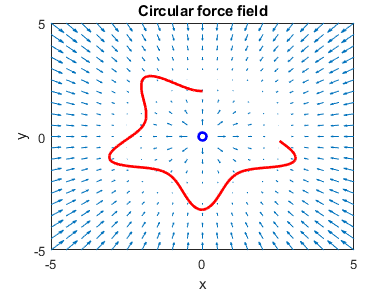


% EULER'S METHOD
for t = 1:i
    ax(t+1) = a(r(x(t),y(t)))*x(t)/r(x(t),y(t));
    ay(t+1) = a(r(x(t),y(t)))*y(t)/r(x(t),y(t));

    vx(t+1) = vx(t) + ax(t)*dt;
    vy(t+1) = vy(t) + ay(t)*dt;
    x(t+1) = x(t) + vx(t)*dt;
    y(t+1) = y(t) + vy(t)*dt; 
    plotParticle(x(1:t),y(1:t),X,Y,Fx,Fy,t,9e7)
end
hold off

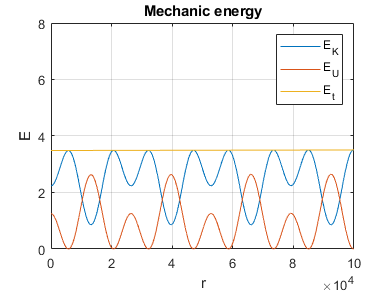


v = sqrt(vx.^2 + vy.^2);
r = sqrt( x.^2 +  y.^2);
t = linspace(0,t,i+1);

% PLOTTING
plot(t,Ek(v))
hold on
plot(t,Ep(r))
plot(t,Ep(r) + Ek(v)); title('Mechanic energy'); grid on
xlabel('r'); ylabel('E'); legend('E_K','E_U','E_t'); ylim([0 8])
hold off

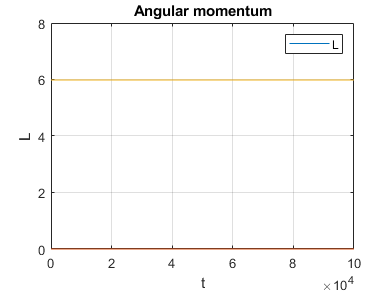


% ANGULAR MOMENTUM CALCULATION
r = [x y zeros(length(r),1)];
v = [vx vy zeros(length(v),1)];
L = m*cross(r,v); 
plot(t,L); title('Angular momentum'); grid on
xlabel('t'); ylabel('L'); legend('L'); ylim([0 8])

function plotParticle(x,y,X,Y,Fx,Fy,t,vel)
    if mod(t,ceil(vel/t)) == 0
        clf
        quiver(X,Y,Fx,Fy); hold on
        plot(0,0,"o","LineWidth",2,"Color","b");
        plot(x,y,'LineWidth',2,'Color','r')
        title('Circular force field');
        xlabel('x'); ylabel('y'); axis([-5 5 -5 5]);
        drawnow
    end
end